# Lab-5

#### Name - Devansh Tanna

#### ID - 2019A3PS0158P

## Task-2

mu = 0;

mu = 0

sigma = sqrt(14);

n_t = sigma*randn(1, 1e4) + mu;
% figure;
% hist(samples, 50);
% hold on;
% xline([mu], 'r--');
% hold off;
% grid on;
% n_t> sigma
% clear samples;
P_1c = sum(n_t > sigma)/length(n_t);
N = 1e4-1

N = 9999

m = -N:N

m =        -9999       -9998       -9997       -9996       -9995       -9994       -9993       -9992       -9991       -9990       -9989       -9988       -9987       -9986       -9985       -9984       -9983       -9982       -9981       -9980       -9979       -9978       -9977       -9976       -9975       -9974       -9973       -9972       -9971       -9970       -9969       -9968       -9967       -9966       -9965       -9964       -9963       -9962       -9961       -9960       -9959       -9958       -9957       -9956       -9955       -9954       -9953       -9952       -9951       -9950


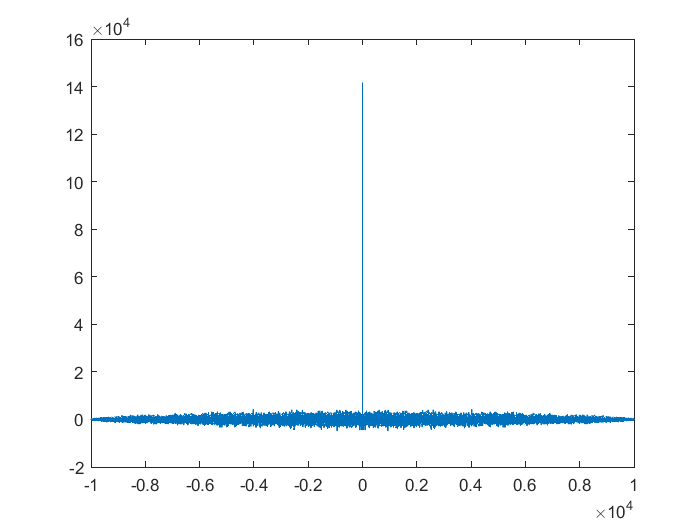

[n_acf, lags] = xcorr(n_t);
n_acf = n_acf-(N-abs(m))*(mu)^2;
plot(lags, n_acf);


$$R_{xx}(m) = \frac{\sum_{n=0}^{N-m-1}(x_n-\bar{x})(x_{n+m}-\bar{x})}{\sum_{n=0}^{N-m-1}(x_n-\bar{x})^2}$$
    


$$\therefore \sum_{n=0}^{N-m-1}(x_nx_{n+m}) + (N-m)c^2$$


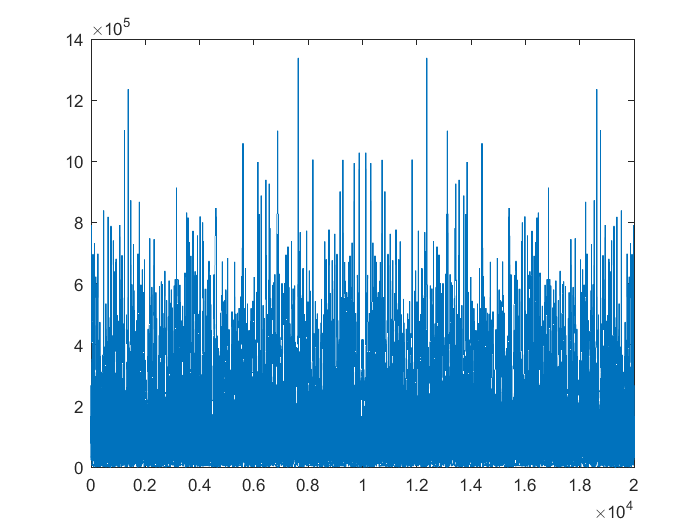

nt_PSD = fftshift(abs(fft(n_acf)));
plot(nt_PSD);

% xlim([980 1020]);

Using Q Function,


$$P(n(t)\gt \sigma)  = P(n(t)-\mu \gt \sigma-\mu)\\
\therefore P\left(\frac{n(t)-\mu}{\sigma}>\frac{\sigma-\mu}{\sigma}\right) = Q\left(x>\frac{\sigma-\mu}{\sigma}\right)\\
$$


Putting all the values and using **Q Function** table,


$$Q\left(x>\frac{3\ldotp 7414-13}{3\ldotp 7417}\right)=Q\left(x>-2\ldotp 4744\right)=0\ldotp 9933$$


which is almost equal to simulated value `.`

P_Q = 

Invalid expression. Check for missing or extra characters.

P_Q = 0.9933

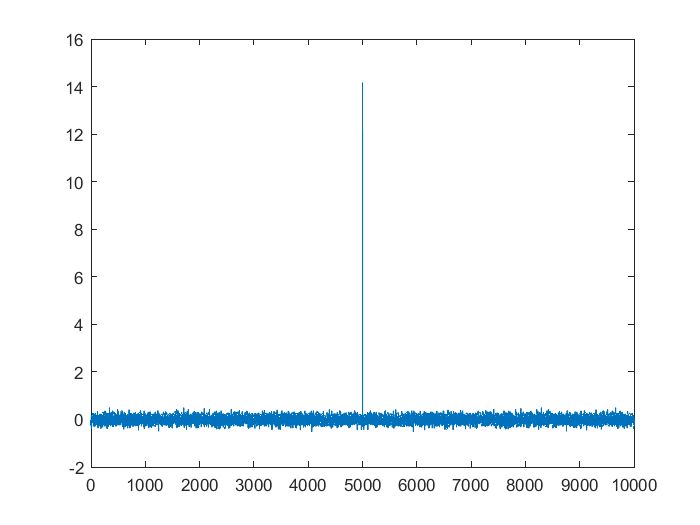

xf = fft(n_t);
fv = fftshift(ifft(xf.*conj(xf)))/N;
plot(fv);

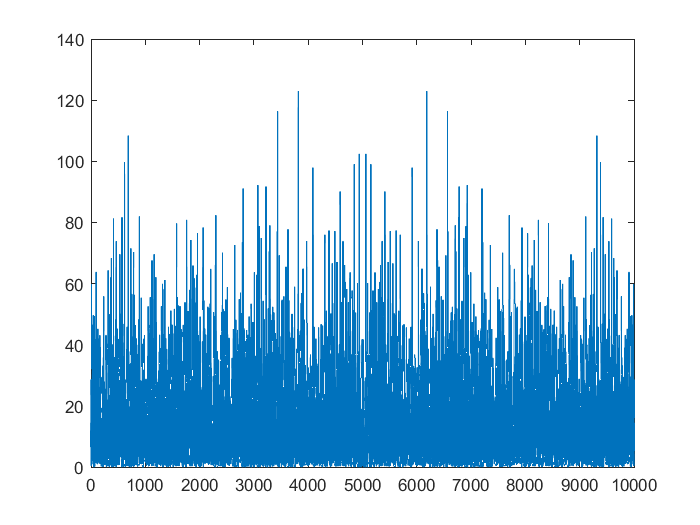

plot(fftshift(abs(fft(fv))));